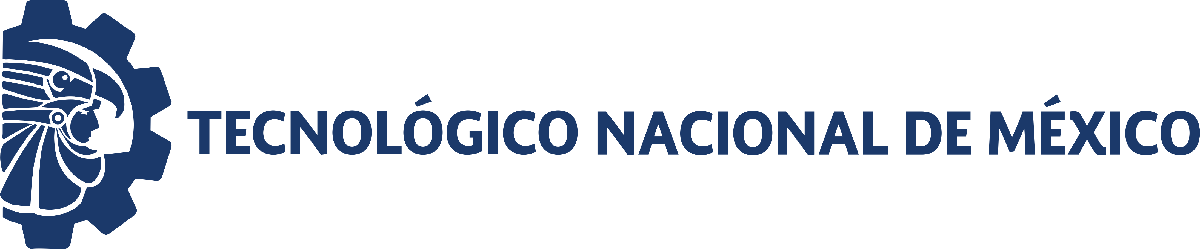                                 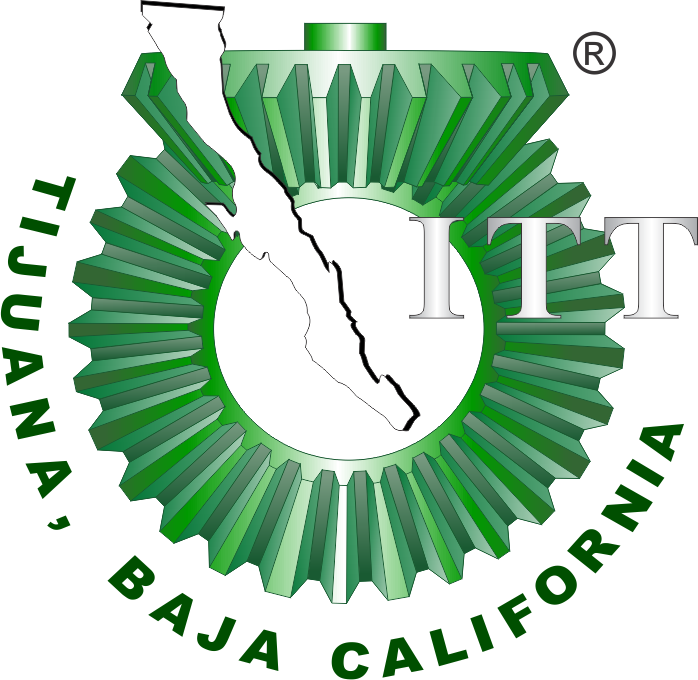

# Práctica dos: Sistema endócrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

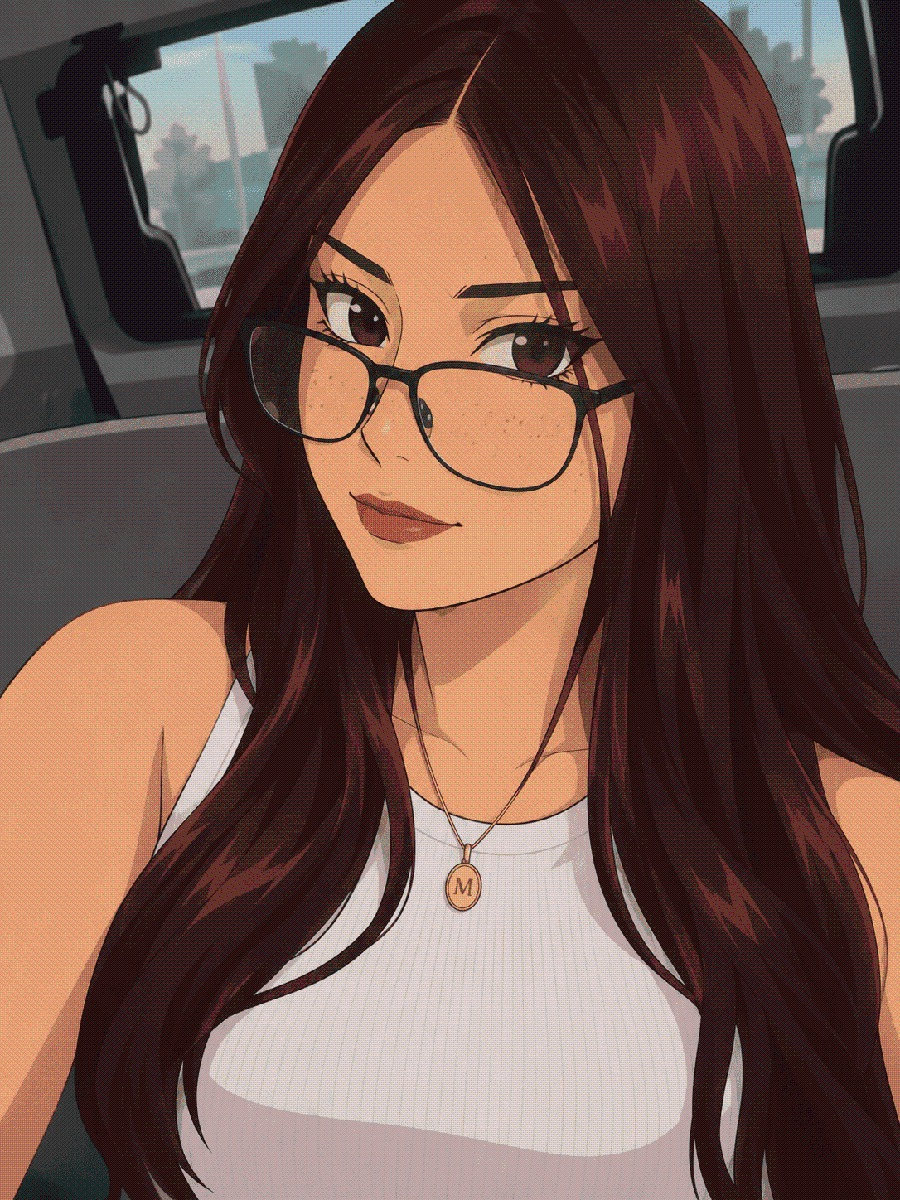

Nombre del alumno: Mildred Angel Torales

Número de control: 23212731

Correo institucional: l23212731**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('Practica4_MSF1_MAT')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x= sim('Practica4_MSF1_MAT',parameters);

## Control y caso

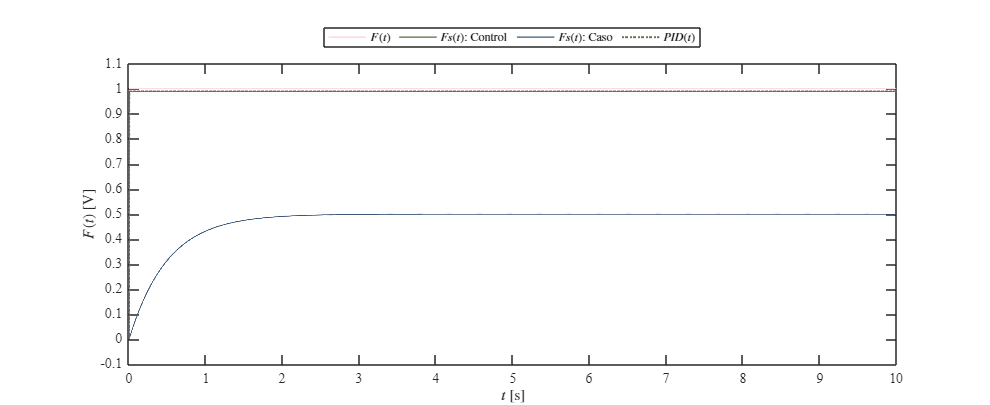

plotsignals(x.t,x.Ve,x.Fsx,x.Fsy,x.PID,'Control&Caso')

## Funcion: Respuesta de simulacion 


function plotsignals(t,Ve,Fsx,Fsy,PID,name)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,11,4.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    
    
    clr1 = [255, 206, 216]/255;
    clr2 = [84, 107, 65]/255;
    clr3 = [62, 88, 121]/255;
    clr4 = [112, 109, 84]/255;
    order = [clr1;clr2;clr3;clr4]; colororder(order)

    plot (t,Ve,'-','LineWidth',1,'Color',clr1)
    plot (t,Fsx,'-','LineWidth',1,'Color',clr2)
    plot (t,Fsy,'-','LineWidth',1,'Color',clr3)
    plot (t,PID,':','LineWidth',1.5,'Color',clr4)
    L = legend('$F(t)$','$Fs(t)$: Control','$Fs(t)$: Caso','$PID(t)$');


    set(L,'interpreter','latex','location','northoutside','orientation','horizontal')

    xlabel('$t$ [s]','interpreter','latex')
    ylabel('$F(t)$ [V]','interpreter','latex')

    xlim([0 10]); xticks(0:1:15)
    ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)

    exportgraphics(gcf,['matlab_',name,'.pdf'],'contenttype','vector')
end